# Difference methods for solving parabolic equations

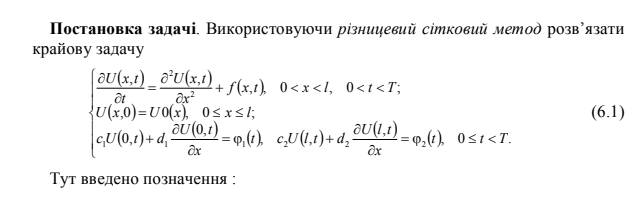

## Taks 1

% параметри модельної задачі :
l=2; c1=1; d1=0; c2=0; d2=1;

% параметри різницевої схеми :
N=51; N1=N-1; h=l/N1; x=0:h:l; x(N)=l;
tau=2e-4; M=25000;

% обчислення додаткових констант (з урахуванням крайових умов) :
gam=tau./(h.*h); D2=2.*h./d2;

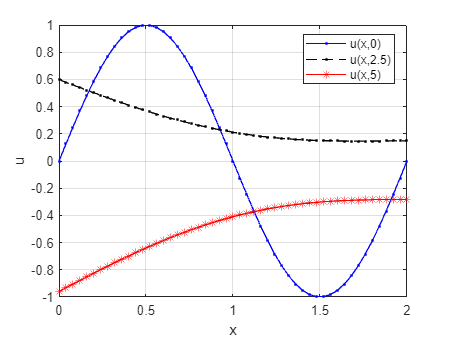

% формування початкових умов при t=0 :
Y = zeros(N, 1);
for k=1:N
    Y(k)=lr6_u0(x(k));
end
Y0=Y; % запам'ятовуємо для побудови графіку розв'язку в t=0
for j=1:M
    % знаходження наближеного розв'язку Y(:) на черговому шарі t=t(j) :
    t=(j-1).*tau;
    t1=t+0.5.*tau;
    yc=Y(1);
    Y(1)=lr6_fi1(t+tau);
    for k=2:N1
        yl=yc; yc=Y(k);
        Y(k)=yc+gam.*(yl-2.*yc+Y(k+1))+tau.*lr6_f(x(k),t1);
    end
    yl=yc; yc=Y(N); yr=yl+D2.*lr6_fi2(t);
    Y(N)=yc+gam.*(yl-2.*yc+yr)+tau.*lr6_f(l,t1);
    if j*2==M
        Y1=Y; % запам'ятовуємо для побудови графіку розв'язку в t=M*tau/2
    end
end

% побудова графіків розв'язку при t=0, M*tau/2, M*tau :
t=M.*tau; t1=t./2; T1=num2str(t1); T=num2str(t);
plot(x,Y0,'b.-',x,Y1,'k.--',x,Y,'r*-');
xlabel('x');
ylabel('u');
legend('u(x,0)',strcat('u(x,',T1,')'),strcat('u(x,',T,')'),'Location','Best');
grid on;

## Taks 2

% параметри задачі :
l=2; c1=1; d1=0; c2=0; d2=1;

% параметри різницевої схеми :
N=51; N1=N-1; h=l/N1; x=0:h:l; x(N)=l;
tau=1e-2; M=500;
sigma=0.5;

% обчислення додаткових констант (з урахуванням крайових умов) :
gam=tau./(h.*h); gs=gam.*sigma; gs2=2.*gs; s1=1-sigma; gs1=gam.*s1;
ck=1+gs2; ckj=1-2.*gs1; D2=2.*h./d2; D2gs=gs.*D2;

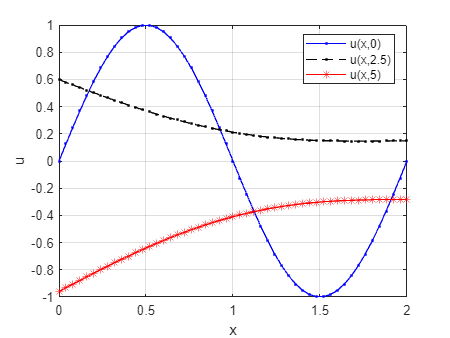

% формування початкових умов при t=0 і матриці СЛАР :
A = zeros(N, 1); B = zeros(N, 1); C = zeros(N, 1);
for k=1:N
    Y(k)=lr6_u0(x(k));
    A(k)=gs; C(k)=ck; B(k)=gs;
end
A(1)=0; C(1)=1; B(1)=0; % враховуємо крайові умови при x=0
A(N)=gs2; B(N)=0; % враховуємо крайові умови при x=l
Y0=Y; % запам'ятовуємо для побудови графіку розв'язку в t=0

for j=1:M
    % знаходження наближеного розв'язку Y(:) на черговому шарі t=t(j) :
    t=j.*tau;
    t1=t-0.5.*tau;

    % формування правої частини СЛАР :
    F(1)=lr6_fi1(t);
    for k=2:N1
        F(k)=gs1.*(Y(k-1)+Y(k+1))+ckj.*Y(k)+tau.*lr6_f(x(k),t1);
    end
    F(N)=gs1.*(2.*Y(N-1)+D2.*lr6_fi2(t-tau))+ckj.*Y(N)+tau.*lr6_f(l,t1)+D2gs.*lr6_fi2(t);
    
    % розв'язок СЛАР, знаходження Y(:) :
    [Y,alfa,err]=m_progm(A,C,B,F);
    if j*2==M
        Y1=Y; % запам'ятовуємо для побудови графіку розв'язку в t=M*tau/2
    end
end

% побудова графіків розв'язку при t=0, M*tau/2, M*tau :
t=M.*tau; t1=t./2; T1=num2str(t1); T=num2str(t);
plot(x,Y0,'b.-',x,Y1,'k.--',x,Y,'r*-');
xlabel('x');
ylabel('u');
legend('u(x,0)',strcat('u(x,',T1,')'),strcat('u(x,',T,')'),'Location','Best');
grid on;

function [y, alfa, err]  =  m_progm(a, c, b, f) 
    n = length(c); err = 0; k = 0;
    while k < n && ~err
        k = k + 1;
        err = err | abs(c(k))< abs(a(k)) + abs(b(k));
    end
    alfa = zeros(1, n); y = alfa;
    if err
        return
    end
    n1 = n - 1;
    % пряма прогонка:
    beta = alfa;
    for k = 1 : n1
        j = k + 1; z = c(k) - a(k) .* alfa(k);
        alfa(j) = b(k) ./ z; beta(j) = (f(k) + a(k) .* beta(k)) ./ z;
    end
    % зворотна прогонка:
    y(n) = (f(n) + a(n) .* beta(n)) ./ (c(n) - a(n) .* alfa(n));
    for k = n1 : -1 : 1
        j = k+1; y(k) = alfa(j) .* y(j) + beta(j);
    end
end

function f=lr6_f(x,t)
    % Функція f(x,t)
    f=(1 - x/2)*(cos(t) - x*sin(t));
end

function u=lr6_u0(x)
    % Функція u0(x)
    u=sin(pi.*x);
end

function fi1=lr6_fi1(t)
    % Функція fi1(t)
    fi1=sin(t);
end

function fi2=lr6_fi2(t)
    % Функція fi2(t)
    fi2=0;
end